### **SISO Communication System using QPSK Modulation **

In QPSK, each symbol is represented by 2 bits: the first bit (or odd bits) corresponds to the real part, and the second bit (or even bits) corresponds to the imaginary part of the symbol in 'symvec'. Each symbol energy Es is normalized to 1, and the Gray-coded symbols are as follows:

11→ $\frac{1}{\sqrt{2}}+i\frac{1}{\sqrt{2}}$

01→ $-\frac{1}{\sqrt{2}}+i\frac{1}{\sqrt{2}}$

11→ $-\frac{1}{\sqrt{2}}-i\frac{1}{\sqrt{2}}$

10→ $\frac{1}{\sqrt{2}}-i\frac{1}{\sqrt{2}}$

Gray mapping is used to minimize bit error rate by ensuring only one bit change between adjacent symbols.

Since each symbol is represented by 2 bits in QPSK modulation, the relationshop between symbol energy $E_s$ and bit energy $E_b$ is given by $E_s =kE_b$, where $k$ is the number of bits per symbol. For QPSK, k can be derived from $\log_2 M$, where M=4 is the number of distinct symbols. This gives the relation $E_s =2E_b$.

When converting from $\frac{E_s }{N_0 }\left(\textrm{dB}\right)$ to $\frac{E_b }{N_0 }\left(\textrm{dB}\right)$, we use the formula:


$$\frac{E_s }{N_0 }\left(\textrm{dB}\right)=\frac{E_b }{N_0 }\left(\textrm{dB}\right)+10\log_{10} \left(k\right)$$


For QPSK, k=2. $10\log_{10} \left(2\right)\approx 3\left(\textrm{dB}\right)$

Thus,


$$\frac{E_b }{N_0 }\left(\textrm{dB}\right)=\frac{E_s }{N_0 }\left(\textrm{dB}\right)-3\left(\textrm{dB}\right)$$


### **Simulation Setup**

M=4;              % QPSK
m=2;              % represent each symbol with 2 bits
Es=1;             % symbol energy
Nbits = 1e6;      % number of bits
Rs = 1;           % symbol rate
Fs = 4;           % sampling rate
sps = Fs/Rs;      % samples per symbol
EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);
hrrc = rrc2((-6:1/sps:6)',0.2,1); % Generate square-root raised cosine(rrc) pulse shaping filter 

% Tx
bitvec = randi([0,1],[Nbits,1]); % Generate random bits
symvec = complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2);

### AWGN Channel, Sample Level

Now, we are passing our QPSK-modulated waveform through a root-raised-cosine (RRC) pulse shaping filter and then through an additive white Gaussian noise (AWGN) channel. We are sampling the signal over a range of SNR values from -3 dB to 20 dB. Our goal is to compare the bit error rate (BER) obtained from demodulation with the theoretical BER for Gray-mapped QPSK. The BER for QPSK is given by the following expression: 


$$\begin{array}{l}
\rho =Q\left(\sqrt{\frac{E_s }{N_0 }}\right)\\
{\textrm{BER}}_{\textrm{QPSK}} =\rho \cdot \left(1-\frac{1}{2}\rho \right)
\end{array}$$


The transmitted signal 'txvec' is obtained by upsampling the QPSK complex symbol vector 'symvec' and then convolving it with the RRC filter 'hrrc'.

The variable 'sig2' represents the noise power, $\sigma^2$. This value changes with SNR because $N_0$ (the noise power spectral density) is dependent on SNR. In the equation, $\frac{N_0 }{2}$ is used instead of $N_0$ since the noise power is equally distributed between the real and imaginary components of the signal for QPSK modulation.

The line "noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)))" generates complex noise with a standard normal distribution (mean=0, standard deviation=1). The noise is then scaled by 'sqrt(sig2)' to adjust for different SNR levels, ensuring that the noise power corresponds to the desired SNR. 

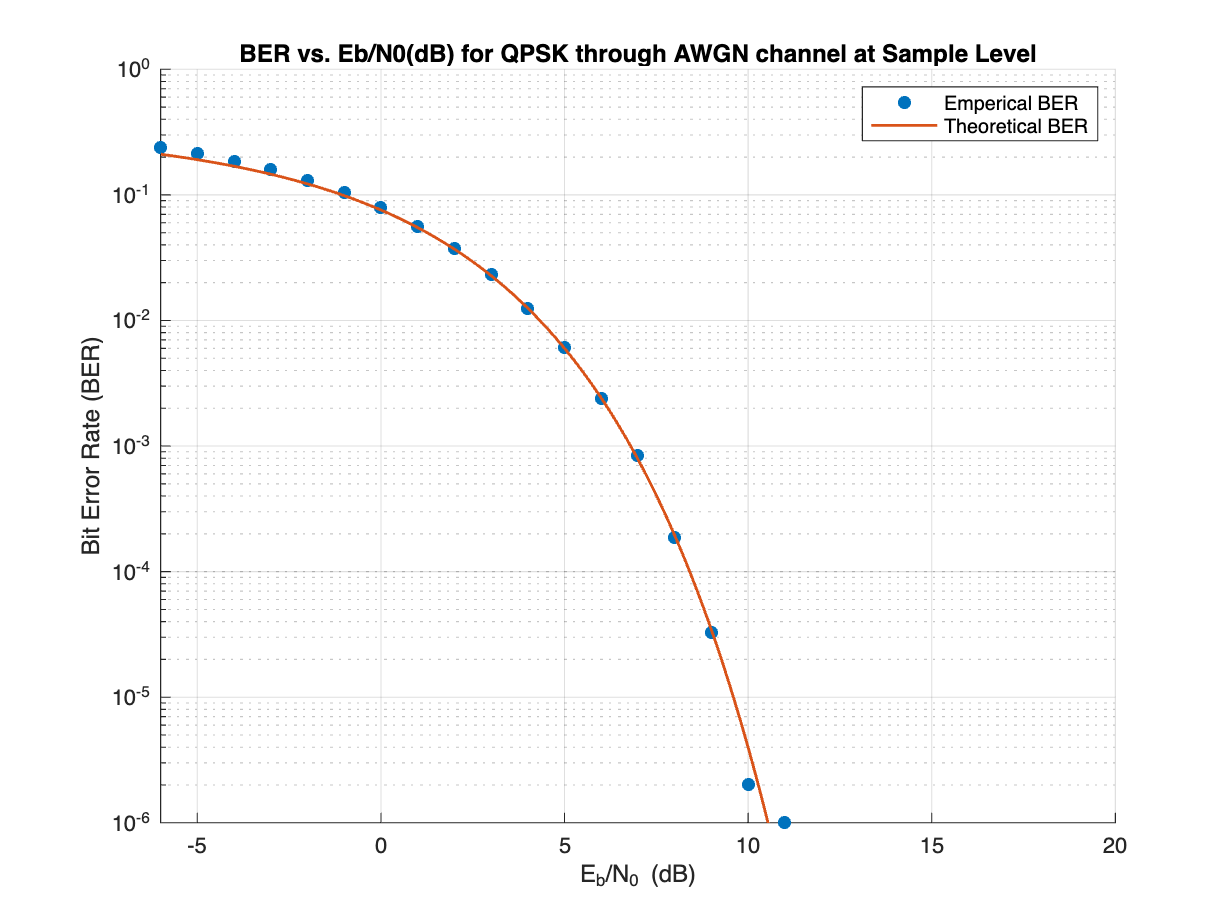

txvec = conv(upsample(symvec,sps),hrrc,'same');

% AWGN channel
% sample level
BER=zeros(1,length(EsN0dB));
for i=1:length(EsN0dB)
    
    sig2 = (N0(i)/2)*Fs;
    noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
    % Rx
    rxvec = txvec + noisevec; % length=(2e6x1)
    
    % Pass the received signal rxvec through a match filter, hrrc(T-t),
    matched_filter=conv(rxvec,hrrc,'same');            % y(t)=rxvex*hrrc
    matched_filter_sample=matched_filter(1:sps:end);   % downsample y(t)

    % Demodulation
    [decoded_syms,decoded_bits]=qpskdetect(matched_filter_sample);
    BER(i)=sum(xor(bitvec,decoded_bits))/Nbits;
end

% theoretical BER for gray-mapping QPSK
EsN0dB2 = -3:0.1:20;
EbN0dB2 = EsN0dB2 - 3;
N02 = 10.^(-EsN0dB2/10);
BER_th=qfunc(sqrt(Es./N02)).*(1-0.5.*qfunc(sqrt(Es./N02)));

clf;    
figure; 
scatter(EbN0dB,BER,'filled')
set(gca,'yscale','log')
hold on
plot(EbN0dB2,BER_th,'LineWidth',1.3)
xlim([-6 20])
ylim([10e-7 1])
grid on
hold off
xlabel('E_b/N_0 (dB)', 'Interpreter', 'tex');
ylabel('Bit Error Rate (BER)');
title('BER vs. Eb/N0(dB) for QPSK through AWGN channel at Sample Level')
legend('Emperical BER','Theoretical BER')

### AWGN Channel, Symbol Level

Compare sample level simulation to symbol level simulation.

The results show that the performance is consistent across both symbol level and sample level simulations.

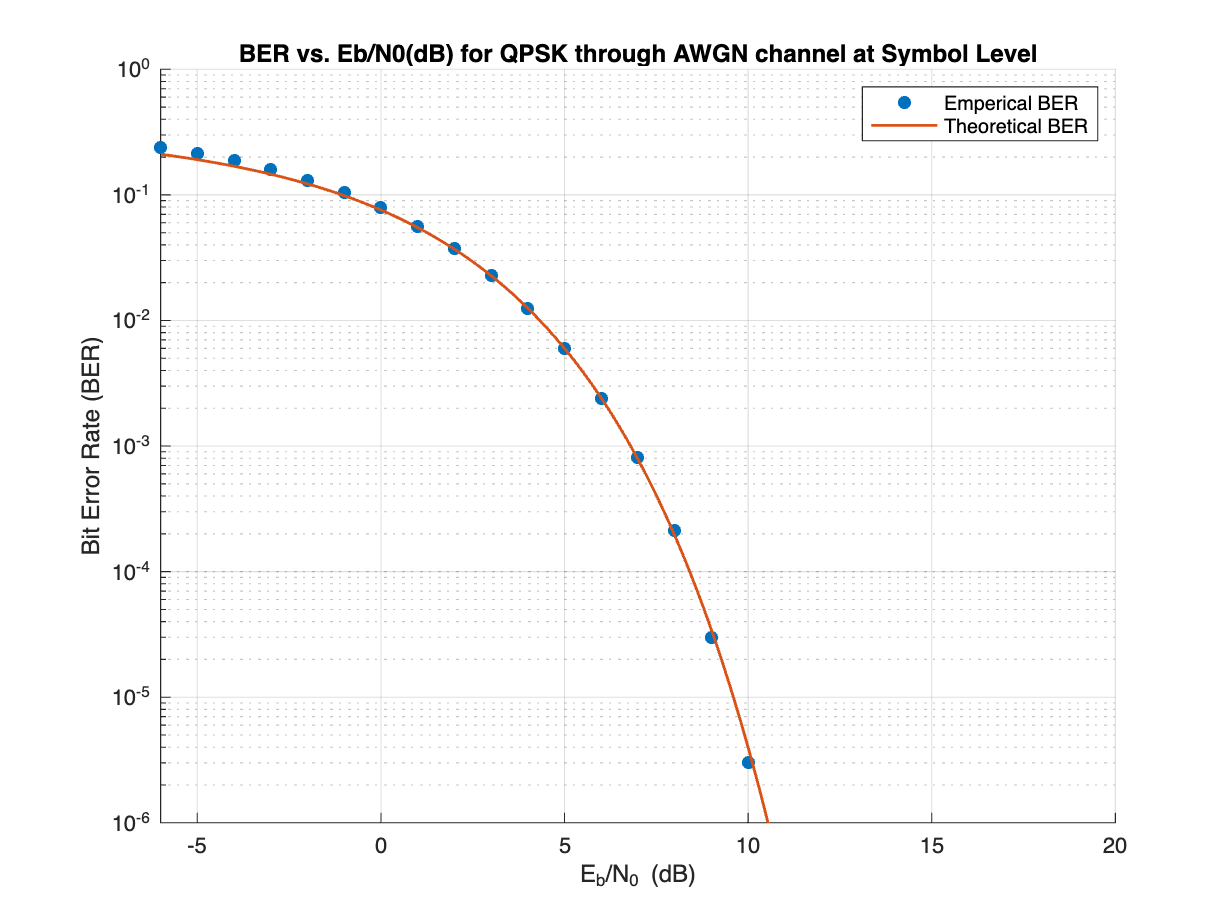

BER2=zeros(1,length(EsN0dB));
SER2=zeros(1,length(EsN0dB)); % symbol error rate

% symbol level
for i=1:length(EsN0dB)
    
    sig2 = N0(i)/2;  % notice that we don't have to multiply noise power with Fs here
    symnoise = sqrt(sig2)*complex(randn(size(symvec)),randn(size(symvec)));
    % Rx
    rxsymvec = symvec + symnoise; % length=(0.5e6x1)

    % Demodulation
    [decoded_syms2,decoded_bits2] = qpskdetect(rxsymvec);

    SER2(i) = sum(decoded_syms2~=symvec)/(Nbits/2);
    BER2(i) = sum(xor(decoded_bits2,bitvec))/Nbits;
end

% theoretical BER for gray-mapping QPSK
EsN0dB2 = -3:0.1:20;
EbN0dB2 = EsN0dB2 - 3;
N02 = 10.^(-EsN0dB2/10);
BER_th=qfunc(sqrt(Es./N02)).*(1-0.5.*qfunc(sqrt(Es./N02)));

figure; 
scatter(EbN0dB,BER2,'filled')
set(gca,'yscale','log')
hold on
plot(EbN0dB2,BER_th,'LineWidth',1.3)
xlim([-6 20])
ylim([10e-7 1])
grid on
hold off
xlabel('E_b/N_0 (dB)', 'Interpreter', 'tex');
ylabel('Bit Error Rate (BER)');
title('BER vs. Eb/N0(dB) for QPSK through AWGN channel at Symbol Level')
legend('Emperical BER','Theoretical BER')

### Impulse Response of RRC Filter

'rrc2' is the rewritten version of the RRC pulse shaping filter function, which serves the same purpose as the original function 'rrc' but is implemented differently.

In the following equation, the roll-off factor is denoted by β, which corresponds to α as used in this project. $T_s =\frac{1}{R_s }$.

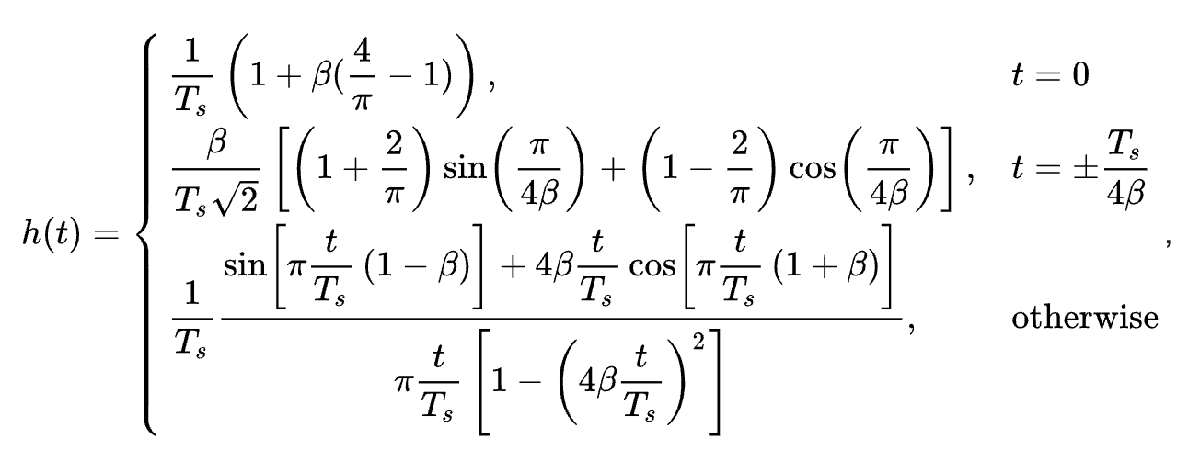

Equation1. Impulse Response of RRC Filter

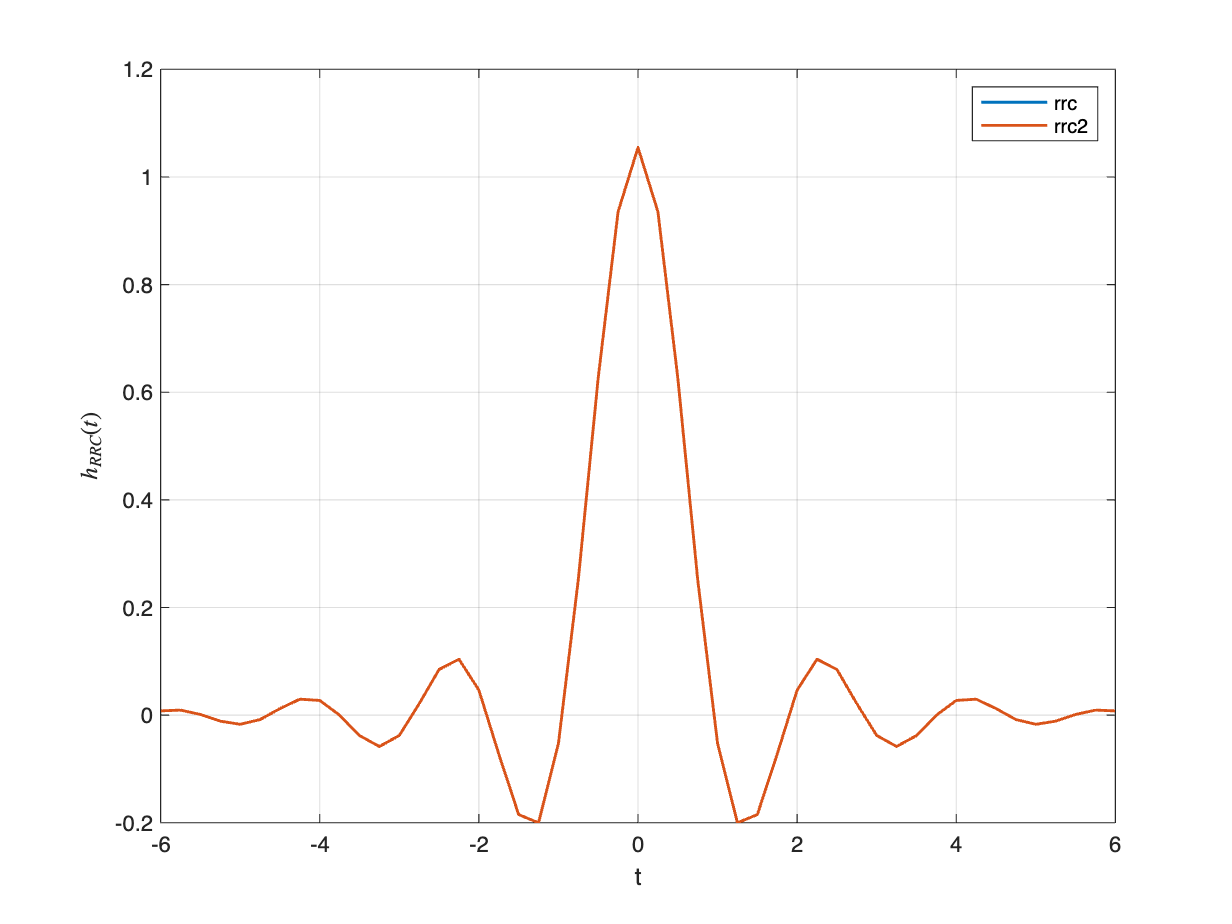

t=(-6:1/sps:6)';
alpha=0.2;
T=1/Rs;
hrrc=rrc(t,alpha,T);
hrrc2=rrc2(t,alpha,T);

figure;
plot(t,hrrc,'LineWidth',1.3)
hold on
plot(t,hrrc2,'LineWidth',1.3)
hold off
grid on
xlabel('t')
ylabel('$h_{RRC}(t)$', 'Interpreter', 'latex')
legend('rrc','rrc2')

### Effect of RRC Filter Roll-off Factor $\alpha$ on BER

Roll-factor $\alpha$ of RRC filter measures the additional bandwidth that the filter occupies beyond the Nyquist bandwidth in frequency domain. The Nyquist bandwidth is defined as $B_{\textrm{Nyquist}} =\frac{1}{2T}$, where $T=\frac{1}{R_s }$.

Although an RRC filter with a higher roll-off factor $\alpha$ requires more bandwidth, it has a smoother impulse response in the time domain (Figure 1), which reduces overlap between adjacent symbols and better prevents intersymbol interference (ISI). In contrast, an RRC filter with a lower roll-off factor $\alpha$ uses less bandwidth but has a sharper, more jittery impulse response, leading to higher BER due to increased ISI. 

Thus, there's a trade-off between bandwidth and BER: 

Higher roll-off factors improve BER at the cost of additional bandwidth, while lower roll-off factors conserve bandwidth but can result in higher BER due to greater ISI.

From the plot 'Impact of RRC Roll-off Factor on BER,' we observe that a roll-off factor of α = 0 results in a higher BER compared to α = 1. The result is consistent with the expectation based on our analysis.

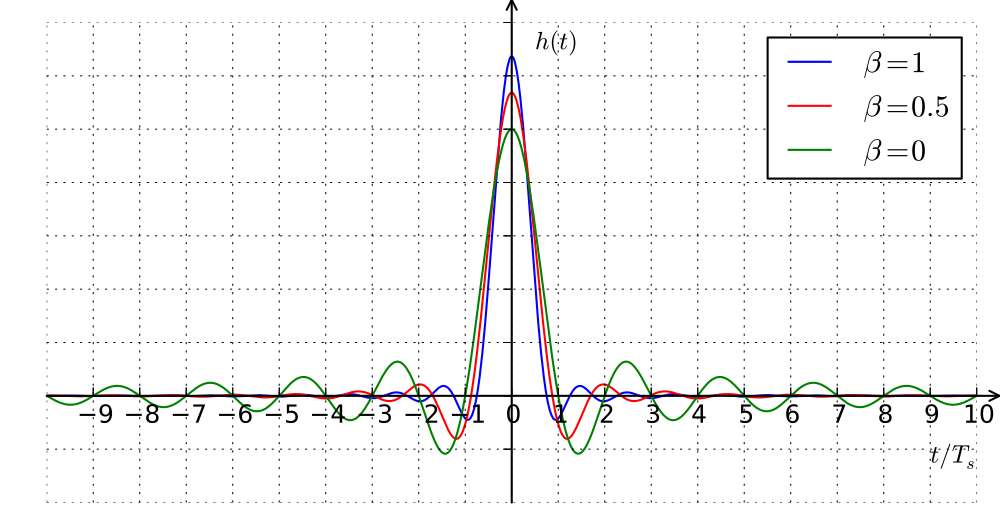

Figure 1. Impulse response of RRC filter in time domain (*Wikipedia: Root-raised-cosine filter, *[*https://en.wikipedia.org/wiki/Root-raised-cosine_filter*](https://en.wikipedia.org/wiki/Root-raised-cosine_filter)* )*

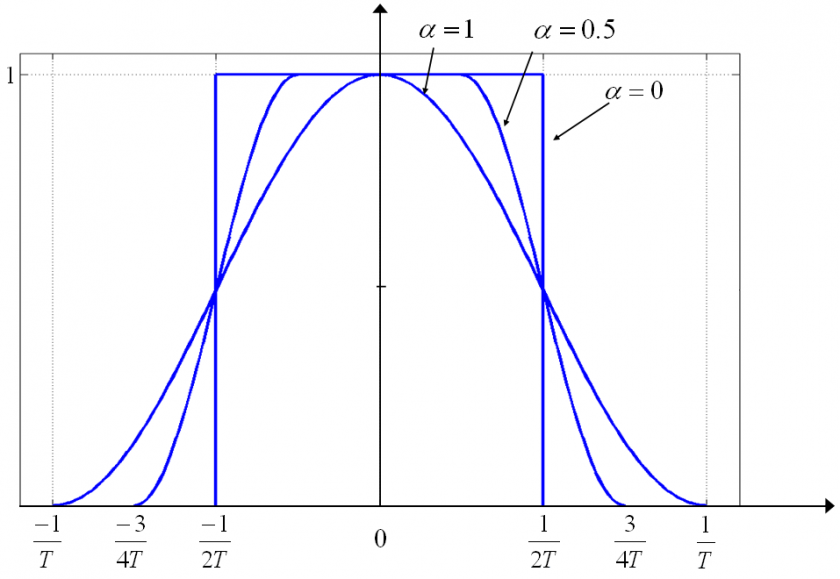

Figure 2. Impulse response of RRC filter in frequency domain *(Navipedia: Root-raised-cosine signals, *[*https://gssc.esa.int/navipedia/index.php/Square-Root_Raised_Cosine_Signals_%28SRRC%29*](https://gssc.esa.int/navipedia/index.php/Square-Root_Raised_Cosine_Signals_%28SRRC%29)* )*

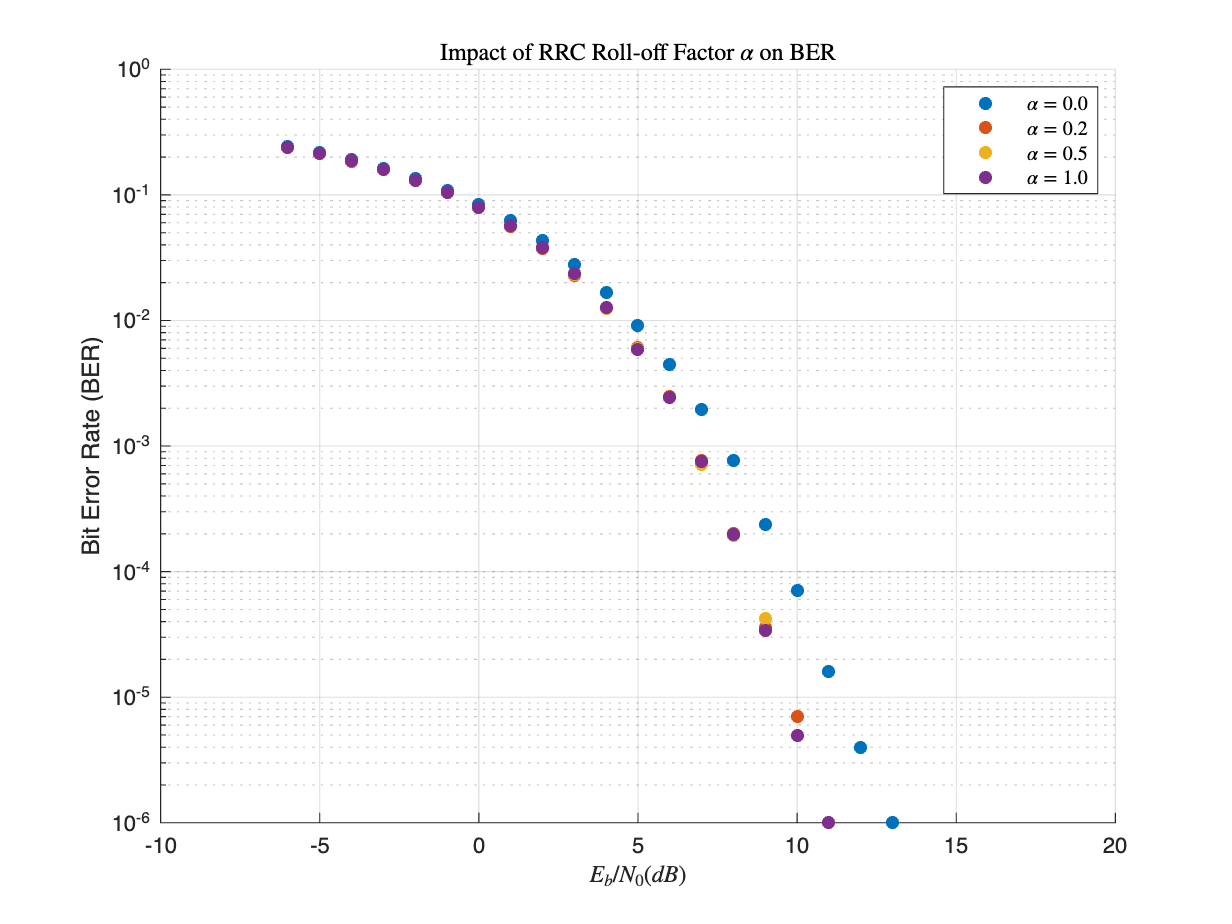

alpha=[0 0.2 0.5 1];
for k=1:length(alpha)
    hrrc = rrc2((-6:1/sps:6)',alpha(k),1); 
    
    % Tx
    bitvec = randi([0,1],[Nbits,1]); % Generate random bits
    symvec = complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2);
    txvec = conv(upsample(symvec,sps),hrrc,'same');
    
    BER=zeros(1,length(EsN0dB));
    for i=1:length(EsN0dB)
        
        sig2 = (N0(i)/2)*Fs;
        noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
        % Rx
        rxvec = txvec + noisevec; % length=(2e6x1)
        
        matched_filter=conv(rxvec,hrrc,'same');            % y(t)=rxvex*hrrc
        matched_filter_sample=matched_filter(1:sps:end);   % downsample y(t)
    
        % Demodulation
        [syms,decoded_bits]=qpskdetect(matched_filter_sample);
        BER(i)=sum(xor(bitvec,decoded_bits))/Nbits;
    end
    scatter(EbN0dB,BER,'filled','DisplayName',sprintf('$\\alpha=%.1f$', alpha(k)));
    hold on
end

set(gca,'yscale','log')
grid on
hold off
xlabel('$E_b/N_0 (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('Impact of RRC Roll-off Factor $\alpha$ on BER', 'Interpreter', 'latex');
legend('Interpreter', 'latex')

### Comparison of BER perdormance for RRC Filters with Different Roll-off factor $\alpha$ but Equal Bandwidth

In this section, we're comparing two RRC filters with roll off factor $\alpha =0$ and $\alpha =1$ with the same bandwidth. To achieve this, we double the bandwidth impulse reponse with $\alpha =0$ (see the figure). This increase in bandwidth results in a doubling of symbol rate. To accomodate this change, we also double the sampling rate (Fs). This adjustment ensure that both cases have the same number of samples per symbol (sps=Fs/Rs) and consistent time resolution for the waveform. 

*case 1: *

- *Roll off factor: *$\alpha =0$

- Symbol rate: ${2R}_s$

- Nyquist bandwidth: $B_{\textrm{Nyquist}} =$$\frac{2}{T}$

- Bandwidth used: $\frac{2}{T}$

case 2:

- *Roll off factor: *$\alpha =1$

- Symbol rate: $R_s$

- Nyquist bandwidth: $B_{\textrm{Nyquist}} =$$\frac{1}{T}$

- Bandwidth used: $\frac{2}{T}$

*Assumption:* 

Given that rect() ($\alpha =0$) impulse response has a more jittery tail in time domain, it is expected to exhibit a higher BER compered to RRC filter with roll off factor of $\alpha =1$.

*Question:* 

How does BER change when the symbol rate is doubled with fixed roll off factor $\alpha =0$? Compare BERs of RRC filter with symbol rate Rs to that of an RRC filter with synbol rate 2Rs.

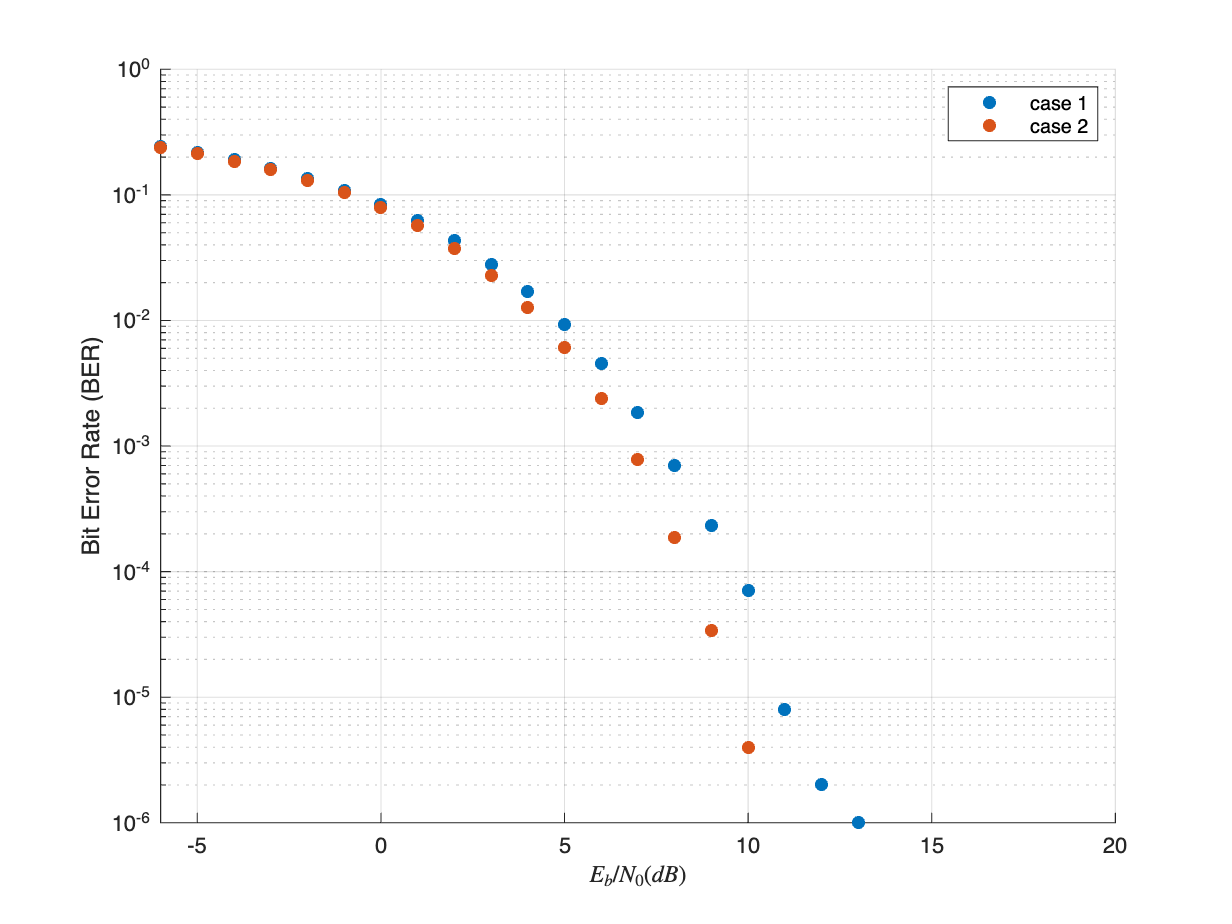

clf;
figure;
Nbits1 = 1e6;    
Nbits2 = 1e6;
Nbitss = [Nbits1 Nbits2];
Rs1 = 1; 
Rs2 = 2;
T1=1/Rs1;
T2=1/Rs2;
Fs1 = 4;   
Fs2 = 8;
Fss = [Fs1 Fs2];
sps1 = Fs1/Rs1;     
sps2 = Fs2/Rs2;
spss=[sps1 sps2]; % sps1 and sps2 should be the same
alpha1=0;
alpha2=1;
EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);
hrrc1 = rrc2((-6:1/sps1:6)',alpha1,T1);  % RRC filter for case 1
hrrc2 = rrc2((-6:1/sps2:6)',alpha2,T2);  % RRC filter for case 2
hrrcs=[hrrc1 hrrc2];

cases=[1 2];

figure;
for k=1:length(cases)
    % Tx
    bitvec = randi([0,1],[Nbitss(k),1]); 
    symvec = complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1)/sqrt(2);
    txvec = conv(upsample(symvec,spss(k)),hrrcs(:,k)','same');
    BER=zeros(1,length(EsN0dB));
    for i=1:length(EsN0dB)
        
        sig2 = (N0(i)/2)*Fss(k);
        noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
        % Rx
        rxvec = txvec + noisevec; % length=(2e6x1)
        
        % Pass the received signal rxvec through a match filter, hrrc(T-t),
        matched_filter=conv(rxvec,hrrcs(:,k)','same');            % y(t)=rxvex*hrrc
        matched_filter_sample=matched_filter(1:spss(k):end);   % downsample y(t)
    
        % Demodulation
        [syms,decoded_bits]=qpskdetect(matched_filter_sample);
        BER(i)=sum(xor(bitvec,decoded_bits))/Nbits;
    end
    scatter(EbN0dB,BER,'filled','DisplayName',sprintf('case %d',cases(k)))
    hold on
end
    


set(gca,'yscale','log')
hold off
xlim([-6 20])
ylim([10e-7 1])
grid on

xlabel('$E_b/N_0 (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('')
legend;

### Slow Flat Fading Channel (Sample Level Simulation)

When a signal is transmitted from a transmitter to a receiver, it often travels through multiple paths, a phenomenon known as multipath propagation. Each path may introduce different levels of attenuation and phase shifts. When these signals converge at the receiver, their alignment in amplitude and phase can lead to either constructive or destructive interference, resulting in fluctuations in signal strength over time called "fading." This effect can be quantified by the fading channel coefficient, h.

***Fading Channel Coefficient: ***$h=a\cdot e^{-j\theta } =x+\textrm{jy}$, which $a=|h|$ is the amplitude and $\theta =\angle h$ is the phase of fading channel coefficient.


$$a=\sqrt{x^2 +y^2 }$$



$$\theta =\tan^{-1} \left(\frac{y}{x}\right)$$


***Flat Fading: ***A flat fading channel exhibits uniform attenuation across the entire bandwidth of the transmitted signal, affecting all frequency components equally. This means the signal is transmitted without distortion, though it may be uniformly attenuated or amplified. (Distortion occurs when different frequency components of the transmitted signal experience different levels of attenuation and phase shift in frequency domain, altering the signal's original shape.)

***Slow Fading:*** Fading channel coefficient, h, varies slowly over time. Happens when obstacles or transimtter and receiver either move slowly or remain static.

'sigfad': $|h|$

'fadingalpha': $h=|h|\cdot e^{-j\theta }$

fadingalpha = sigfad(n)*complex(randn(1),rand(1));

In the above code, we generate a random fading channel coefficient h with its amplitude 'sigfad' |h|. We then multiply |h| by a randomly generated complex number, where both the real and imaginary parts follow a standard normal distribution, ensuring the  phase is uniformly distributed over $-\pi$ to $\pi$.

Suppose we have a complex $Z=X+\textrm{jY}$, $X~N\left(0,1\right)$ and $Y~N\left(0,1\right)$, and X is independent of Y


$$f_{\textrm{XY}} \left(x,y\right)=f_X \left(x\right)\cdot f_Y \left(y\right)=\frac{1}{\sqrt{2\pi }}e^{\frac{-x^2 }{2}} \cdot \frac{1}{\sqrt{2\pi }}e^{\frac{-y^2 }{2}} =\frac{1}{2\pi }e^{\frac{-\left(x^2 +y^2 \right)}{2}}$$



$$f_{A\Theta } \left(a,\theta \right)=\frac{a}{2\pi }e^{\frac{-a^2 }{2}}$$


$f_A \left(a\right)=\int_{-\pi }^{\pi } \frac{a}{2\pi }e^{\frac{-a^2 }{2}} d\theta =2a{\cdot e}^{-a^2 }$...Rayleigh distribution

$f_{\Theta } \left(\theta \right)=$$\int_0^{\infty } \frac{a}{2\pi }e^{\frac{-a^2 }{2}} \textrm{da}=\frac{1}{2\pi }$...uniform distribution, $\left\lbrack -\pi ,\pi \right\rbrack$

***Coherence Bandwidth:***

$B_c$: coherence bandwidth (flat portion of channel bandwidth)

$B_s$: signal bandwidth

(a) $B_s$<$B_c$ $\longrightarrow$Flat fading without distortion             (b) $B_s$>$B_c$ $\longrightarrow$Frequency selective channel with distortion

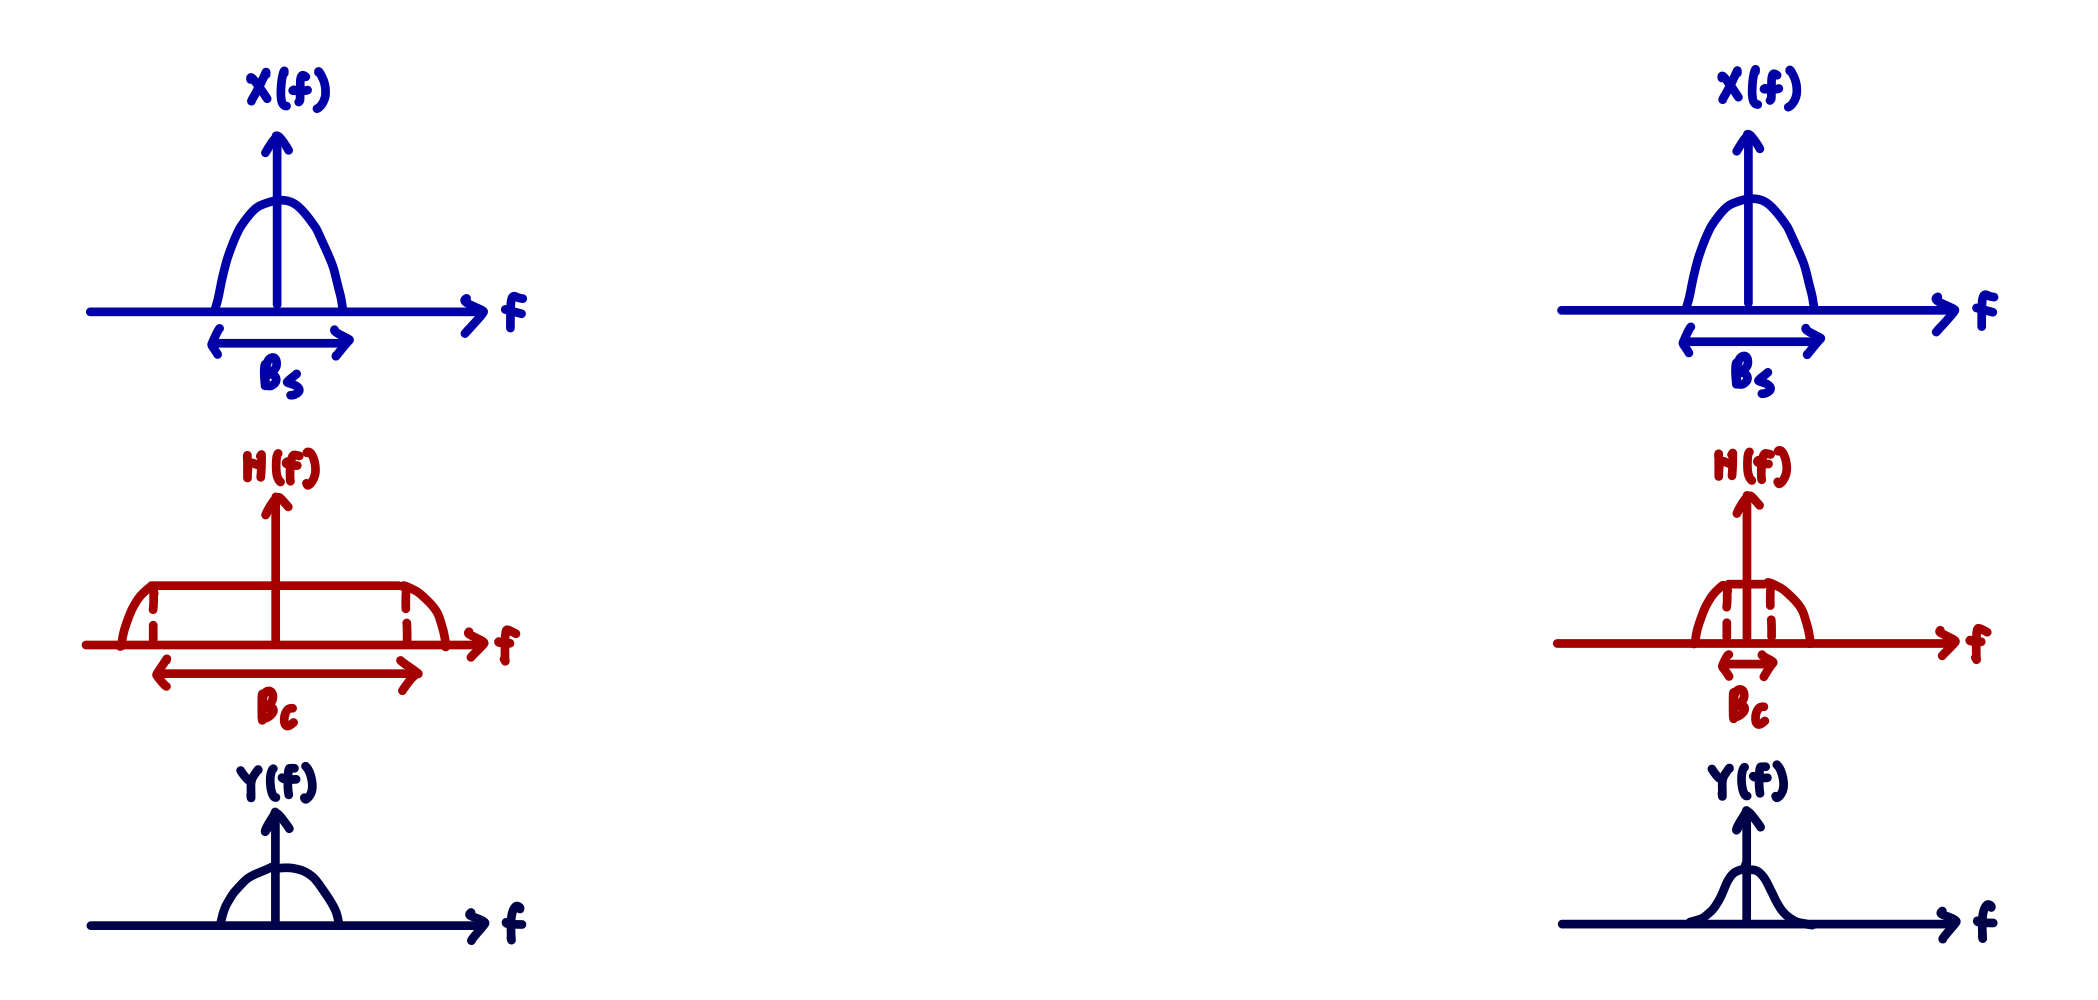

In frequency domain, we have $|Y|=|X|\cdot |H|$, where $|X|$ and $|Y|$ are transmitted and received signals, and $|H|$ is the impulse response of the channel. In case (a), the signal bandwidth $B_s$ is within the flat portion of channel bandwidth $B_c$, so all frequency components of the signal are attenuated equally as they pass through the channel. As a result, no distortion occurs. In case (b), since signal bandwidth $B_s$ is wider than the channel bandwidth $B_c$, the transmitted signal gets distorted.

***Phase Compensation:***

mfout = conv(rxvecfad*exp(-1i*angle(fadingalpha)),hrrc,'same')/Fs;

In this step, we correct the phase shift introduced by channel fading during transmission. This process, known as phase compensation, involves applying the inverse of the phase shift caused by the channel to the received signal.

compare experimental result with theoretical value

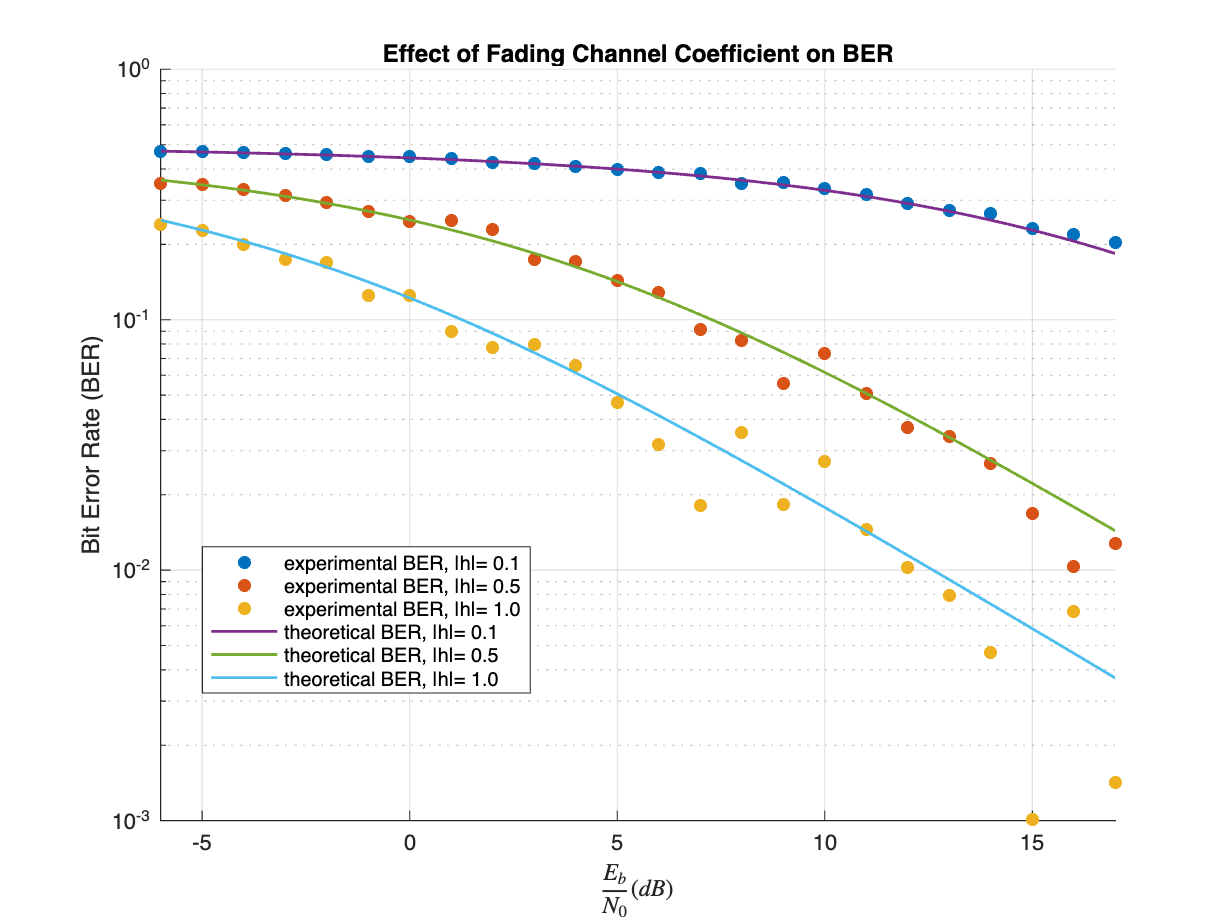

%% Flat fading
% sample-level simulation
clf;
figure;
Nbits=1e3;
Rs=1;
T=1/Rs;
Fs=4;
sps=Fs/Rs;
alpha=0.2;  % roll-off factor
hrrc=rrc2((-6:1/sps:6)',alpha,T);

EsN0dB = -3:1:20;
EbN0dB = EsN0dB-3; 
N0 = 10.^(-EsN0dB/10);
EsN0dB2 = -3:0.1:20;
EbN0dB2 = EsN0dB2-3; 
N02 = 10.^(-EsN0dB2/10);

bitvec=randi([0,1],[Nbits,1]);
symvec=(1/sqrt(2))*complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1);
txvec = conv(upsample(symvec,sps),hrrc,'same');

sigfad = [0.1 0.5 1];   % |h|: amplitude of fading channel coefficent

ser3=zeros(1,length(EsN0dB));
ber3=zeros(1,length(EsN0dB));

nruns = 100;
for n=1:length(sigfad)

    for i=1:length(EsN0dB)
        sig2 = N0(i)*Fs/2;
        total_symbol_error = 0;
        total_bit_error = 0;
        for k = 1:nruns
            noisevec = sqrt(sig2)*complex(randn(size(txvec)),randn(size(txvec)));
            fadingalpha = sigfad(n)*complex(randn(1),rand(1));  % h=|h|*exp(i*theta), theta=phase of h
            rxvecfad = fadingalpha * txvec + noisevec;
            mfout = conv(rxvecfad*exp(-1i*angle(fadingalpha)),hrrc,'same')/Fs; % phase compensation
            mfsamp = mfout(1:sps:end);
            [detsymvec,detbitvec] = qpskdetect(mfsamp);
            total_symbol_error = total_symbol_error + sum(detsymvec~=symvec)/(Nbits/2);
            total_bit_error = total_bit_error + sum(xor(detbitvec,bitvec))/Nbits;
        end
        ser3(i) = total_symbol_error/nruns;
        ber3(i) = total_bit_error/nruns;
    end
    
    scatter(EbN0dB,ber3,'filled','DisplayName',sprintf('experimental BER, |h|= %.1f',sigfad(n)));
    hold on
end

% theoretical BER for QPSK modulation with flat fading channel
for n=1:length(sigfad)
    SNR_fad=sigfad(n)^2*Es./N02; % SNRs affected by fading channel
    BER_th=0.5*(1-sqrt(SNR_fad./(1.5+SNR_fad)));
    plot(EbN0dB2,BER_th,'LineWidth',1.3,'DisplayName',sprintf('theoretical BER, |h|= %.1f',sigfad(n)))
end


set(gca,'yscale','log')
hold off
xlim([-6 17])
ylim([1e-3 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('Effect of Fading Channel Coefficient on BER')
legend("Position", [0.1641 0.2503 0.2661, 0.1583]);

### Slow Flat Fading Channel (Symbol Level Simulation)

Compare sample level simulation to symbol level simulation.

The results show that the performance is consistent across both symbol level and sample level simulations.

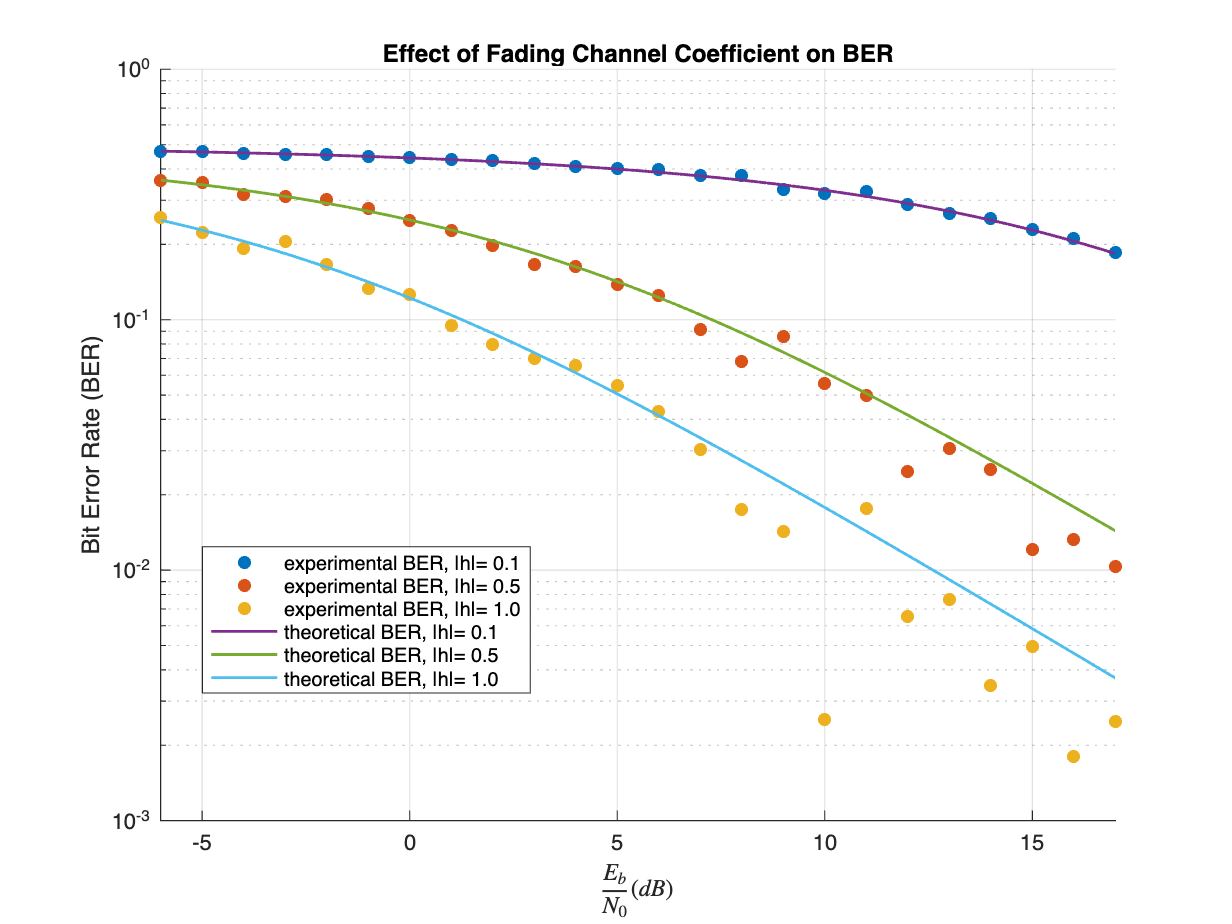

%% Flat fading
% symbol-level simulation
clf;
figure;

bitvec=randi([0,1],[Nbits,1]);
symvec=(1/sqrt(2))*complex(2*bitvec(1:2:end)-1,2*bitvec(2:2:end)-1);

sigfad = [0.1 0.5 1];   % |h|: amplitude of fading channel coefficent

ser4=zeros(1,length(EsN0dB));
ber4=zeros(1,length(EsN0dB));

nruns = 100;
for n=1:length(sigfad)

    for i=1:length(EsN0dB)
        sig2 = N0(i)/2;
        total_symbol_error = 0;
        total_bit_error = 0;
        for k = 1:nruns
            noisevec = sqrt(sig2)*complex(randn(size(symvec)),randn(size(symvec)));
            fadingalpha = sigfad(n)*complex(randn(1),rand(1));  % h=|h|*exp(i*theta), theta=phase of h
            rxvecfad = fadingalpha * symvec + noisevec;
            % Phase compensation
            rxvecfad = rxvecfad*exp(-1i*angle(fadingalpha));
            [detsymvec,detbitvec] = qpskdetect(rxvecfad);
            total_symbol_error = total_symbol_error + sum(detsymvec~=symvec)/(Nbits/2);
            total_bit_error = total_bit_error + sum(xor(detbitvec,bitvec))/Nbits;
        end
        ser4(i) = total_symbol_error/nruns;
        ber4(i) = total_bit_error/nruns;
    end
    
    scatter(EbN0dB,ber4,'filled','DisplayName',sprintf('experimental BER, |h|= %.1f',sigfad(n)));
    hold on
end

% theoretical BER for QPSK modulation with flat fading channel
for n=1:length(sigfad)
    SNR_fad=sigfad(n)^2*Es./N02; % SNRs affected by fading channel
    BER_th=0.5*(1-sqrt(SNR_fad./(1.5+SNR_fad)));
    plot(EbN0dB2,BER_th,'LineWidth',1.3,'DisplayName',sprintf('theoretical BER, |h|= %.1f',sigfad(n)))
end


set(gca,'yscale','log')
hold off
xlim([-6 17])
ylim([1e-3 1])
grid on

xlabel('$\frac{E_b}{N_0} (dB)$', 'Interpreter', 'latex');
ylabel('Bit Error Rate (BER)');
title('Effect of Fading Channel Coefficient on BER')
legend("Position", [0.1641 0.2503 0.2661, 0.1583]);

MIMO